# Using Scoring Matrices to Measure Evolutionary Distance

This example shows how to handle *Scoring Matrices* with the sequence alignment tools. The example uses proteins associated with retinoblastoma, a disease caused by a tumor which develops from the immature retina. 

## Accessing the NCBI Website and Database

More information on [retinoblastoma](http://www.ncbi.nlm.nih.gov/books/NBK22191/) can be found at the [Genes and diseases section](http://www.ncbi.nlm.nih.gov/bookshelf/br.fcgi?book=gnd) of the NCBI web site.

The "BLink" link on this page shows related sequences in different organisms. These links can change frequently, so for this example you can load a set of previously saved data from a MAT-file.

load retinoblastoma

You can also use the `getgenpept` function to retrieve the sequence information from the NCBI data repository and load it into MATLAB.

## Aligning CAH72243 (Human Protein) to CAA51019 (Chicken Protein)

One approach to study the relationship between these two proteins is to use a global alignment with the `nwalign` function. 

[sc,hvc] = nwalign(human,chicken)

sc = 1.4543e+03

hvc = 3×938 char array
    'MPPKTPRKTAATAAAAAAEPPAPPPPPPPEEDPEQDSGPEDLPLVRLEFEETEEPDFTALCQKLKIPDHVRERAWLTWEKVSSVDGVLGGYIQKKKELWGICIFIAAVDLDEMSFTFTELQKNIEISVHKFFNLLKE--I--DT-STKVDNAMSRLLKKYDVLFALFSKLERTCELIYLTQPSSSISTEINSALVLKVSWITFLLAKGEVLQMEDDLVISFQLMLCVLDYFIKLSPPMLLKEPYKTAV--IPINGSPRTPRRGQNRSARIAKQLENDTRIIEVLCKEHECNIDEVKNVYFKNFIPFMNSLGLVTSNGLPEVENLSKRYEEIYLKNKDLDARLFLDHDKTLQTDSIDSFETQRTPRKSNLDEEVNVIPPHTPVRTVMNTIQQLMMILNSASDQPSENLISYFNNCTVNPKESILKRVKDIGYIFKEKFAKAVGQGCVEIGSQRYKLGVRLYYRVMESMLKSEEERLSIQNFSKLLNDNIFHMSLLACALEVVMATYSRSTSQ-NLDSG-TDLSFPWILNVLNLKAFDFYKVIESFIKAEGNLTREMIKHLERCEHRIMESLAWLSDSPLFDLIKQSKDREGPTDHLESACPLNLPLQNNHTAADMYLSPVRSPKKKGSTTRVNSTANAETQATSAFQTQKPLKSTSLSLFYKKVYRLAYLRLNTLCERLLSEHPELEHIIWTLFQHTLQNEYELMRDRHLDQIMMCSMYGICKVKNIDLKFKIIVTAYKDLPHAVQETFKRVLIKEEEYDSIIVFYNSVFMQRLKTNILQYASTRPPTLSPIPHIPRSPYKFPSSPLRIP-GGNIYISPLKSPYKISEGLPTPTKMTPRSRILVSIGESFGTSEKFQKINQMVCNSDRVLKRSAEGSNPPKPLKKLRFDIEGSDEADGSKHLPGESKFQQKLAEMTSTRTRMQKQKMNDSMDTSNKEEK'
    '|||| | : |::| :  : | :     

In this alignment the function used the default scoring matrix, BLOSUM62. Different scoring matrices can give different alignments. How can you find the best alignment? One approach is to try different scoring matrices and look for the highest score. When the score from the alignment functions is in the same scale (in this case, bits) you can compare different alignments to see which gives the highest score. 

This example uses the PAM family of matrices, though the approach used could also be used with the BLOSUM family of scoring matrices. The PAM family of matrices in the Bioinformatics Toolbox™ consists of 50 matrices, PAM10, PAM20,..., PAM490, PAM500. 

Take the two sequences (CAH72243 and CAA51019) and align them with each member of the PAM family and then look for the highest score. 

score = zeros(1,50);
fprintf('Trying different PAM matrices ')

Trying different PAM matrices 

for step = 1:50
   fprintf('.')
   PamNumber = step * 10;
   [matrix,info] = pam(PamNumber);
   score(step) = nwalign(human,chicken,'scoringmatrix',matrix,'scale',info.Scale);
end

..................................................

## Plotting the Scores

You can use the `plot` function to create a graph of the results.

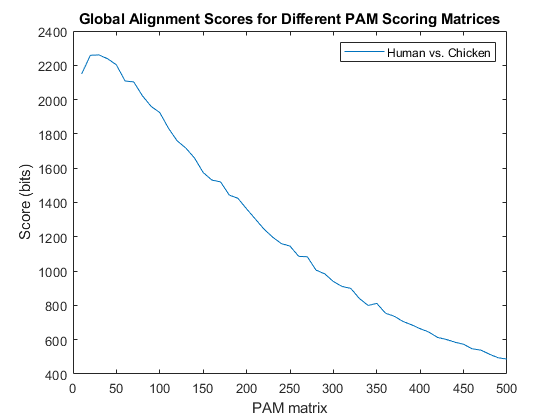

x = 10:10:500;
plot(x,score)
legend('Human vs. Chicken');
title('Global Alignment Scores for Different PAM Scoring Matrices');
xlabel('PAM matrix');ylabel('Score (bits)');

## Finding the Best Score

You can use `max` with two outputs to find the highest score and the index in the results vector where the highest value occurred. In this case the highest score occurred with the third matrix, that is PAM30.

[bestScore, idx] = max(score)

bestScore = 2.2605e+03

idx = 3

## Aligning to Other Organisms

Repeat this with different organisms: xenopus and rainbow trout.

xenopusScore = zeros(1,50);
troutScore = zeros(1,50);
fprintf('Trying different PAM matrices ')

Trying different PAM matrices 

for step = 1:50
   fprintf('.')
   PamNumber = step * 10;
   [matrix,info] = pam(PamNumber);
   xenopusScore(step) = nwalign(human,xenopus,'scoringmatrix',matrix,'scale',info.Scale);
   troutScore(step) = nwalign(human,trout,'scoringmatrix',matrix,'scale',info.Scale);
end

..................................................

## Adding More Lines to the Same Plot

You can use the command `hold on` to tell MATLAB® to add new plots to the existing figure. Once you have finished doing this you must remember to disable this feature by using `hold off`.

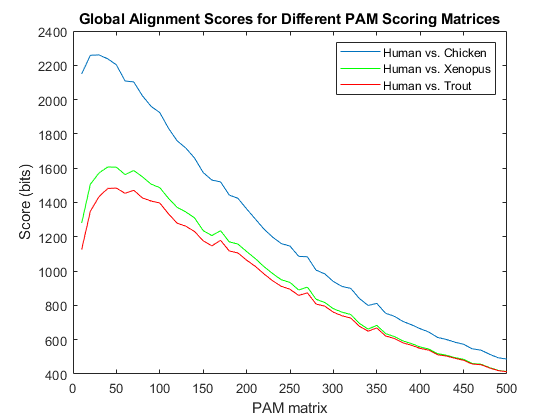

hold on
plot(x,xenopusScore,'g')
plot(x,troutScore,'r')
legend({'Human vs. Chicken','Human vs. Xenopus','Human vs. Trout'});box on
title('Global Alignment Scores for Different PAM Scoring Matrices');
xlabel('PAM matrix');ylabel('Score (bits)');
hold off

## Finding the Best Scores

You will see that different matrices give the highest scores for the different organisms. For human and xenopus, the best score is with PAM40 and for human and trout the best score is PAM50.

[bestXScore, Xidx] = max(xenopusScore)

bestXScore = 1607

Xidx = 4

[bestTScore, Tidx] = max(troutScore)

bestTScore = 1484

Tidx = 5

The PAM scoring matrix giving the best alignment for two sequences is an indicator of the relative evolutionary interval since the organisms diverged: The smaller the PAM number, the more closely related the organisms. Since organisms, and protein families across organisms, evolve at widely varying rates, there is no simple correlation between PAM distance and evolutionary time. However, for an analysis of a specific protein family across multiple species, the corresponding PAM matrices will provide a relative evolutionary distance between the species and allow accurate phylogenetic mapping. In this example, the results indicate that the human sequence is more closely related to the chicken sequence than to the frog sequence, which in turn is more closely related than the trout sequence.

*Copyright 2003-2014 The MathWorks, Inc.*